# Program to show the order of accuracy of NCFDM is first-order

In this program higher-order NCFDM is derived for arbitarly varying non-uniform mesh. This procedure is an extension of the method followed for uniform mesh in :

The grid nomenclature used is:

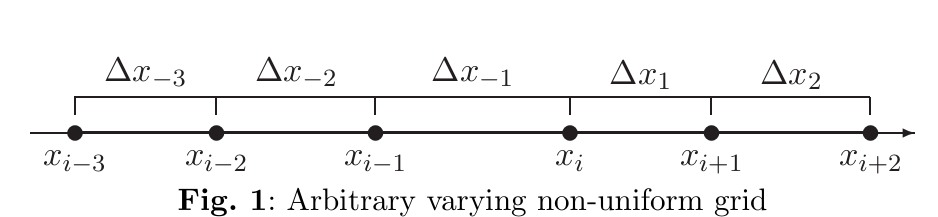

clc
clear all
close all

syms a b c x dx dx_1 dx1 dx_2 dx2 dx3 dx_3

L0=1/(dx_1/2+dx1/2);    % 1/length of 'I'th cell
L_1=1/(dx_1/2+dx_2/2);  % 1/length of 'I-1'th cell
L_2=1/(dx_2/2+dx_3/2);  % 1/length of 'I-2'th cell
L1=1/(dx1/2+dx2/2);     % 1/length of 'I+1'th cell
L2=1/(dx2/2+dx3/2);     % 1/length of 'I+2'th cell

In the conservative discretization, cell-averaged quantity is defined as

 
$$
\bar{\mathbf{U}}=\frac{1}{V}\int_V \mathbf{U} dV
$$


where $V$ is the volume of the cell in three-dimension, area in two-dimension and length in one-dimension. For third order approximation, the variable can be written as


$$\mathbf{U}(\xi) =a+b\xi + c \xi^2$$


 The cell-averaged quantity in the cell $I_i \equiv [i-0.5, i+0.5]$ is defined as


$$\bar{\mathbf{U}}(x) = \frac{1}{\Delta x}\int_{x-0.5\Delta x}^{x+0.5\Delta x} \mathbf{U}(\xi) d \xi$$


after integration, it become


$$\bar{\mathbf{U}}(x) = a + bx +c\left(x^2+\frac{\Delta x^2}{12}\right)$$


Here, $a$, $b$ and $c$ are calculated by substituting $x_i = x_j + (i-j)\Delta x$ for $j=$ -1, 0 and  1, then the gradient of any variable can be calculated using


$$\frac{\partial \mathbf{U}}{\partial x} =\frac{\mathbf{U}_{i+0.5}-\mathbf{U}_{i-0.5}}{\Delta x}$$


and $\mathbf{U}_{i+0.5} = a + b (\frac{\Delta x}{2})  + c (\frac{\Delta x}{2})^2$.

Volume averaged term at different cells can be written as


$$	\bar{\mathbf{U}}_{i-2}=\frac{1}{\Delta x_{-2}}\int_{-(\frac{\Delta x_{0}}{2}+\Delta x_{-1}+\Delta x_{-2})}^{-(\frac{\Delta x_{0}}{2}+\Delta x_{-1})}u(\xi) d\xi \quad 
	\bar{\mathbf{U}}_{i-1}=\frac{1}{\Delta x_{-1}}\int_{-(\frac{\Delta x_{0}}{2}+\Delta x_{-1})}^{-\frac{\Delta x_{0}}{2}} u(\xi) d\xi \quad $$



$$	\bar{\mathbf{U}}_{i}=\frac{1}{\Delta x_0}\int_{-\frac{\Delta x_{0}}{2}}^{\frac{\Delta x_{0}}{2}} u(\xi) d\xi \quad 
	\bar{\mathbf{U}}_{i+1}=\frac{1}{\Delta x_{-1}}\int_{\frac{\Delta x_{0}}{2}}^{(\frac{\Delta x_{0}}{2}+\Delta x_{1})} u(\xi) d\xi $$



$$	\bar{\mathbf{U}}_{i+2}=\frac{1}{\Delta x_{-2}}\int_{(\frac{\Delta x_{0}}{2}+\Delta x_{1})}^{(\frac{\Delta x_{0}}{2}+\Delta x_{1}+\Delta x_{2})}u(\xi) d\xi $$


 % cell averaged quntity at 'I' th cell
bu0=L0*int(a*x^2+b*x+c,-(dx_1/2),+(dx1/2));
                                                
% cell averaged quntity at 'I-1' th cell
bu_1=L_1*int(a*x^2+b*x+c,-(dx_1+dx_2/2),-(dx_1/2));

% cell averaged quntity at 'I-2' th cell
bu_2=L_2*int(a*x^2+b*x+c,-(dx_1+dx_2+dx_3/2),-(dx_1+dx_2/2));

% cell averaged quntity at 'I+1' th cell
bu1=L1*int(a*x^2+b*x+c,dx1/2,dx1+dx2/2);

% cell averaged quntity at 'I+2' th cell
bu2=L2*int(a*x^2+b*x+c,dx1+dx2/2,dx1+dx2+dx3/2);

We can derive $a$, $b$ and $c$ in terms of $\mathbf{\bar{U}}_{i-1}$, $\mathbf{\bar{U}}_{i}$ and $ \mathbf{\bar{U}}_{i+1}$

syms bU0 bU_1 bU_2 bU1 bU2

%(i+0.5) clculation
%Cell interface (i+0.5) calculation
eq1=solve(bu_1-bU_1,bu0-bU0,bu1-bU1,a,b,c);
t1=0.5*dx1;
yp5=simplify(eq1.a*(t1).^2+eq1.b*(t1)+eq1.c); 

Right face flux can be obtained by


$$\mathbf{U}_{i+0.5} = a \left(\frac{\Delta x_{1}}{2}\right)^2 + b \left(\frac{\Delta x_{1}}{2}\right) + c$$


Left face flux can be obtained by


$$\mathbf{U}_{i-0.5} = a \left(\frac{-\Delta x_{-1}}{2}\right)^2 + b \left(\frac{-\Delta x_{-1}}{2}\right) + c$$


eq1=solve(bu_2-bU_2,bu_1-bU_1,bu0-bU0,a,b,c);
t1=-0.5*dx_1;
yp_5=simplify(eq1.a*(t1).^2+eq1.b*(t1)+eq1.c);

The derivative for non-uniform mesh can be approximated as


$$\frac{d\mathbf{{U}}}{dx} = \frac{\mathbf{{U}}_{i+0.5} - \mathbf{{U}}_{i-0.5}}{\Delta x_0 }$$


dy=(yp5-yp_5)*2/(dx1+dx_1); % final appoximation of df/dx
f1=simplify(dy);
disp('df/dx calculated using NCFDM is:')

df/dx calculated using NCFDM is:


disp(f1)

## Order of accuracy calculation

The general form of $n^{th}$ order polynomial is:

$f(x) = a_nx^n+....a_1x+a_0$, its derivative at $x = 0$ is $$\frac{df}{dx} = a_1$$. The numerical scheme is $$n^{th}$$ order, if we substitute $$f_i = f(0)$$, $$f_{i-1} = f(x-h)$$, ... in the derivative formulation and on simplifying, we get $$\frac{df}{dx} = a_1$$. If the scheme is not satisfying the condition, we should reduce the order of the polynomial still it satisfies $$\frac{df}{dx} = a_1$$. The order of the polynomial at which the scheme satisfies the condition is the order of the scheme. Though it is possible to prove the order of accuracy of the scheme by directly expanding Taylors series, we have used polynomial way of proving the order of accuracy of the Taylors series.

Folliwng code to evaluate order of accuracy of the scheme.

t1=first_order(f1);

The scheme is not even first-order


if t1==1
    t1=second_order(f1);
    if t1==1
        t1=third_order(f1);
        if t1==1
            t1=fourth_order(f1);
            if t1==1
                t1=fifth_order(f1);
            end
        end
    end
end